# Train EV Detection Model

## Load the ground truth and create a combined datastore

load parkingTrainGTfinished.mat
gTruth

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [3×5 table]
           LabelData: [400×3 table]


[imds,blds] = objectDetectorTrainingData(gTruth);
nFiles = length(imds.Files);
classes = categories(blds.LabelData{1,2})

classes = 3×1 cell array
    {'Accessible'}
    {'Charger'   }
    {'EV'        }


data = combine(imds,blds);

## Split the data into training and validation sets

data = shuffle(data);
trainingFraction = 0.8;
numTraining = floor(nFiles*trainingFraction);
trainingData = subset(data, 1:numTraining);
validationData = subset(data, (numTraining+1):nFiles);

## Build detector and setup training options

imageSize = [320 480 3];
detector = yoloxObjectDetector("tiny-coco",classes,"InputSize",imageSize);

options = trainingOptions("adam",...
    MiniBatchSize=32,...
    MaxEpochs=10,... 
    ValidationData=validationData,...
    OutputNetwork="best-validation-loss",...
    Shuffle="every-epoch",...
    Plots="training-progress",...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    ValidationFrequency=10);

## Train the model

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingYoloXLoss    ValidationYoloXLoss
    _____    _________    ___________    _________    _________________    ___________________
      1          1         00:00:27        0.001           12.135                12.883       
      1         10         00:03:26        0.001           6.4724                 5.929       
      2         20         00:06:31        0.001           3.9755                4.5802       
      3         30         00:09:41        0.001           3.9353                 4.434       
      4         40         00:12:45        0.001           3.4694                3.8498       
      5         50         00:16:09        0.001           2.8389                3.5841       
      6         60         00:19:4

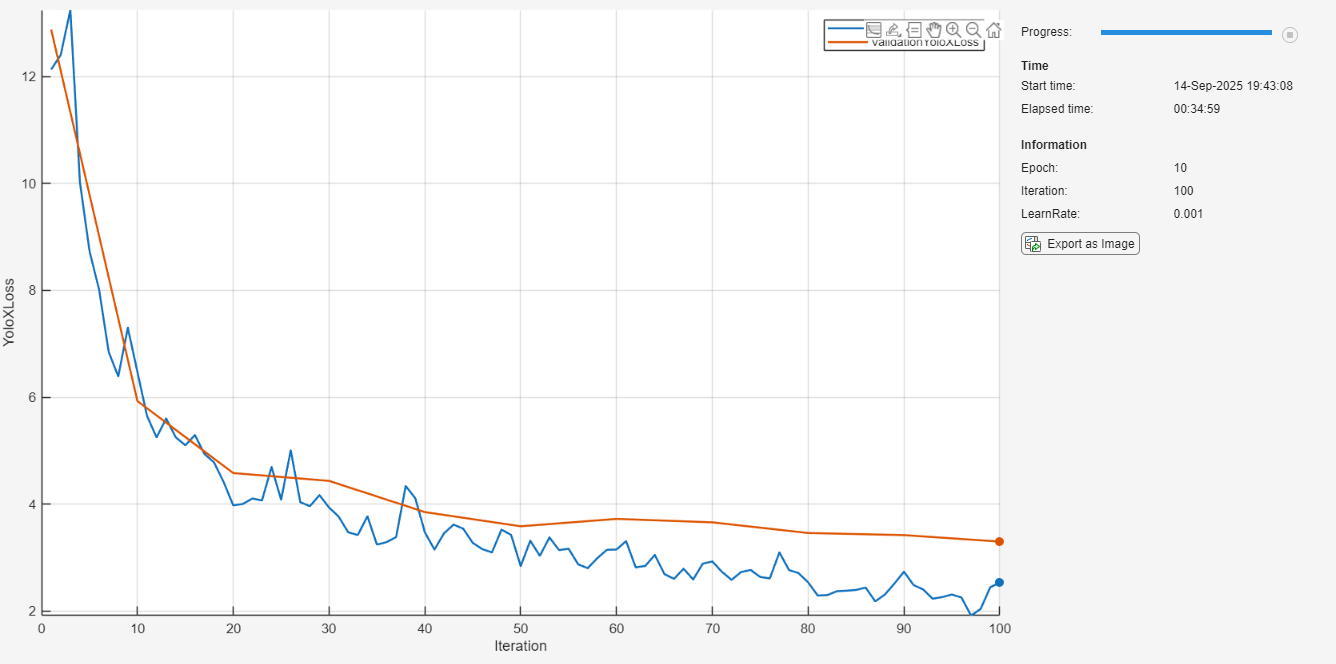

     10         100        00:34:39        0.001           2.5316                3.2974       


evYoloDetector = trainYOLOXObjectDetector(trainingData,detector,options);

## Save results

save('trainedYOLOXDetector.mat', 'evYoloDetector');